## Plot Path

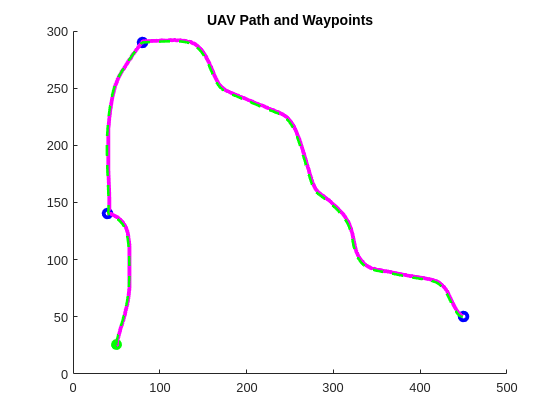

%load map.mat;

f1 = figure(1); clf;
hold on;
%show(map);
plot(position.gps.Data(1,1), position.gps.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8, "DisplayName", "start");
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'LineWidth', 3, "DisplayName", "waypoint"); 
end
%plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
plot(position.true.Data(:,1), position.true.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "actual");
if ~any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3, "DisplayName", "crash");
end
if any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'g^', 'markersize', 14, 'LineWidth', 3, "DisplayName", "success");
end
plot(trajectory.x_ref_points(:,2), trajectory.y_ref_points(:,2), 'g--', 'linewidth', 2, "DisplayName", "reference");
hold off;
title("UAV Path and Waypoints");

%legend('Location',"best");

## Euclidean Position Error

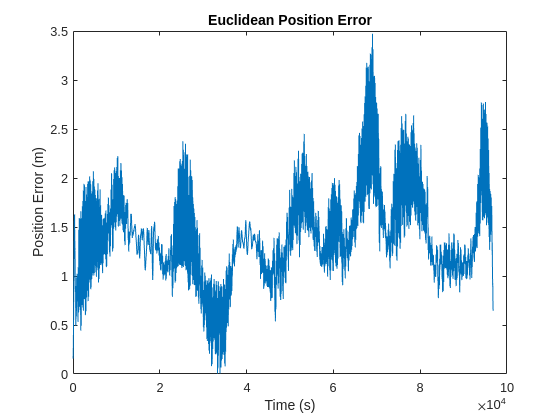

f2 = figure(2); clf;
plot(errors.euclidean_pos_err.Data);
title('Euclidean Position Error');
xlabel("Time (s)");
ylabel("Position Error (m)");

## Voltage and SOC Plot

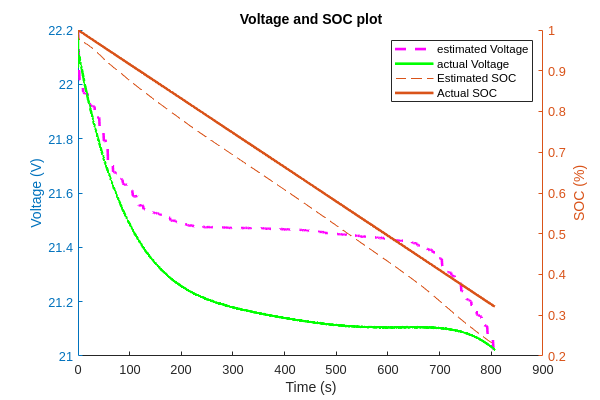

f3 = figure(3); clf;
f3.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery.battery_hat.v.Time(:), battery.battery_hat.v.Data(:,1), 'm--', 'linewidth', 2, "DisplayName", "estimated Voltage");
plot(battery.battery_true.v.Time(:), battery.battery_true.v.Data(:,1), 'g-', 'linewidth', 2, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;

plot(battery.battery_hat.z.Time(:), battery.battery_hat.z.Data(:), '--', "DisplayName", "Estimated SOC");

plot(battery.battery_true.z.Time(:), battery.battery_true.z.Data(:),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
title('Voltage and SOC plot');
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

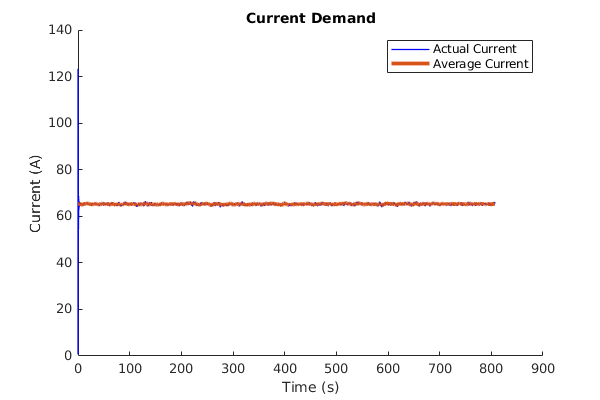

f4 = figure(4); clf;
f4.Position = [0 0 600 400];
hold on;
plot(battery.battery_true.i.Time(:), battery.battery_true.i.Data(:), 'b', 'linewidth', 1, "DisplayName", "Actual Current");
plot(downsample(battery.battery_true.i.Time(:), 20),smoothdata(downsample(battery.battery_true.i.Data(:), 20), 'rlowess', 50), 'linewidth', 3, "DisplayName", "Average Current");
hold off;
title('Current Demand');
xlabel("Time (s)");
ylabel("Current (A)");
legend();